% Load Data
load ADC_Linearity_Data.mat

% Calculate mean and std_dev of each set point
data_mean = mean(data')';
data_std = std(double(data'))';

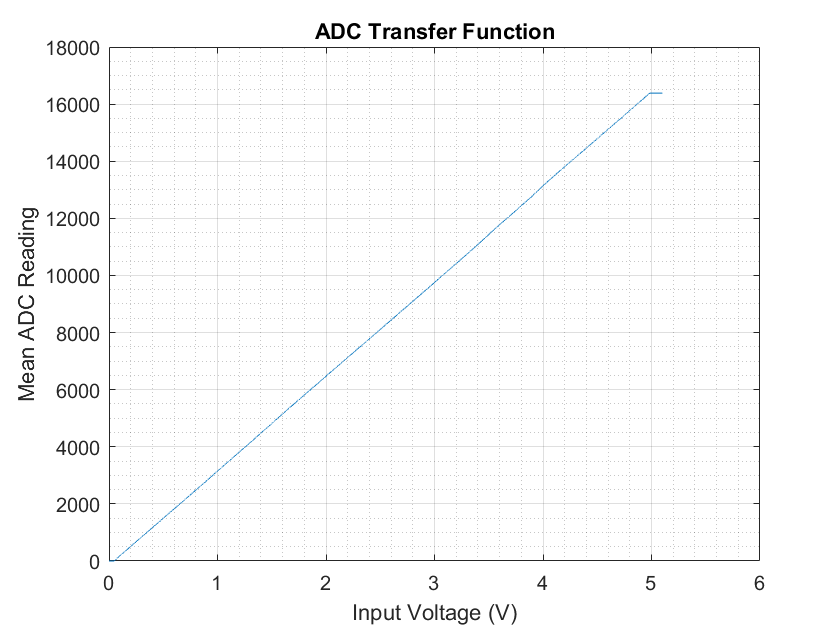

% Plot Transfer Function
figure()
plot(set_point,data_mean);

title('ADC Transfer Function');
grid ON;
grid MINOR;
xlabel('Input Voltage (V)');
ylabel('Mean ADC Reading');

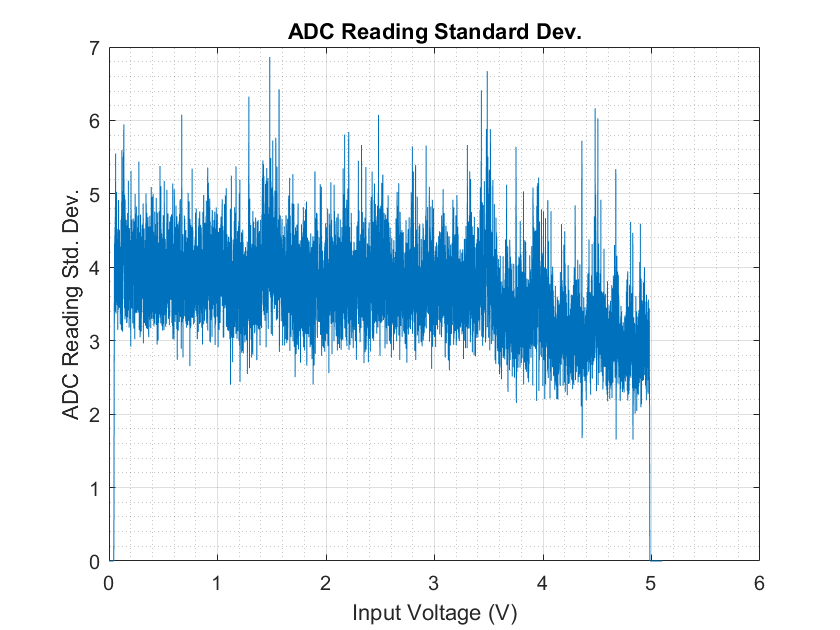


% Plot Std. Deviation:
figure()
plot(set_point,data_std);
title('ADC Reading Standard Dev.');
grid ON;
grid MINOR;
xlabel('Input Voltage (V)');
ylabel('ADC Reading Std. Dev.');

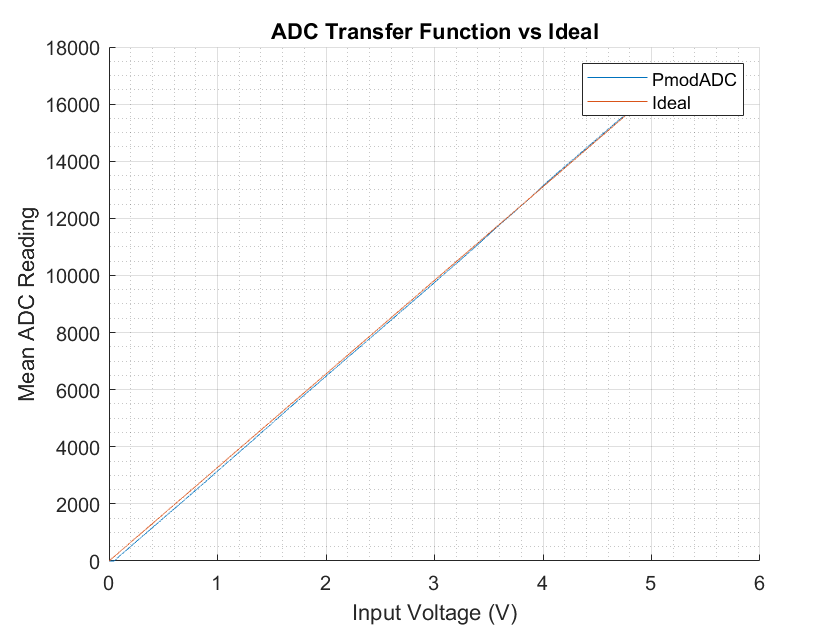

% ADC & Ideal Transfer function
ideal_tf = set_point*((2^14-1)/5);
ideal_tf = round(min(2^14-1,max(ideal_tf,0)),1);

figure()
hold on;
plot(set_point,data_mean);
plot(set_point,ideal_tf);

title('ADC Transfer Function vs Ideal');
grid ON;
grid MINOR;
xlabel('Input Voltage (V)');
ylabel('Mean ADC Reading');
legend('PmodADC','Ideal');

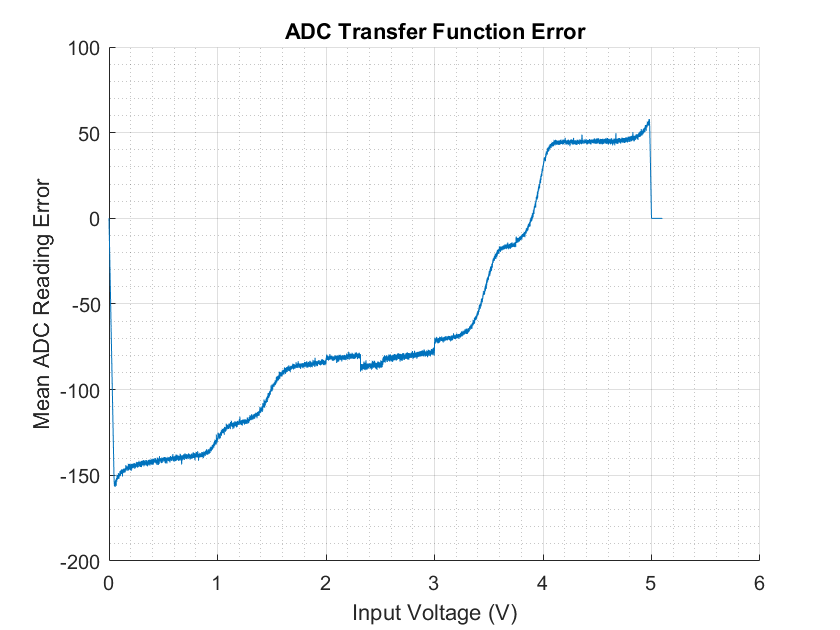


% Error
figure()
hold on;
plot(set_point,data_mean-ideal_tf);
title('ADC Transfer Function Error');
grid ON;
grid MINOR;
xlabel('Input Voltage (V)');
ylabel('Mean ADC Reading Error');

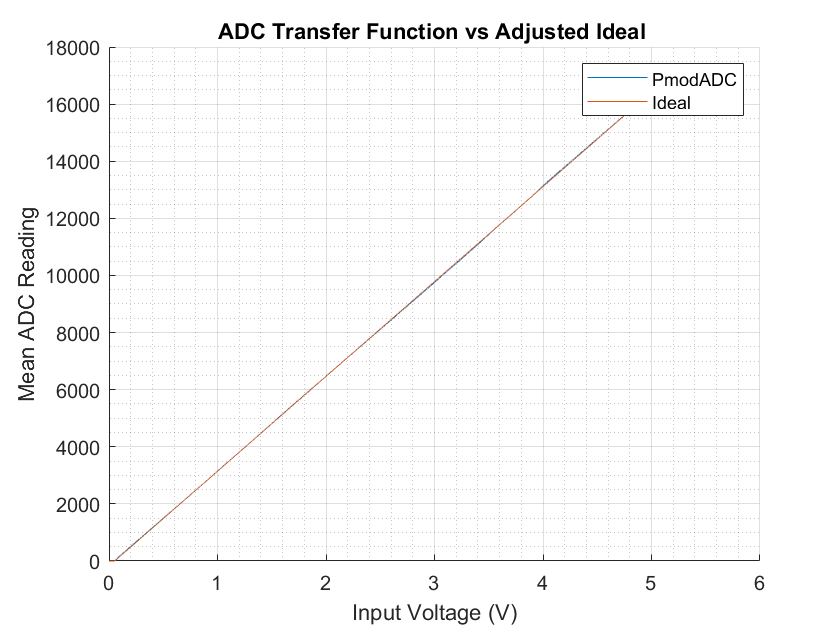

% Error to gain/offset adjusted linear transfer function

% Find linear regression of data, skipping saturation regions at beginning
% and end

r = polyfit(set_point(1000:16000), data_mean(1000:16000),1);
m = r(1);
b = r(2);

% Calculate new linear regression
lin_tf = double(set_point)*m+b;
lin_tf = max(0,min(lin_tf,2^14-1)); % Saturate
lin_tf = round(lin_tf,0);

figure()
hold on;
plot(set_point,data_mean);
plot(set_point,lin_tf);

title('ADC Transfer Function vs Adjusted Ideal ');
grid ON;
grid MINOR;
xlabel('Input Voltage (V)');
ylabel('Mean ADC Reading');
legend('PmodADC','Ideal');


% Error
figure()
hold on;
plot(set_point,data_mean-lin_tf);
title('ADC adjusted Transfer Function Error');
grid ON;
grid MINOR;
xlabel('Input Voltage (V)');
ylabel('Mean ADC Reading Absolute Error');